% 6G THz BPSK Detection: Compare ZF vs k-NN + PCA vs SVM + PCA
clc; clear;

% Parameters
N = 1e5;
SNR_dB_range = 0:2:30;
ber_zf = zeros(size(SNR_dB_range));
ber_knn_pca = zeros(size(SNR_dB_range));
ber_svm_pca = zeros(size(SNR_dB_range));
path_loss = 10;

% Original bitstream and modulated signal (reused across SNRs)
data = randi([0 1], N, 1);
modulated_signal = 2*data - 1;

% Loop through SNR values
for i = 1:length(SNR_dB_range)
    SNR_dB = SNR_dB_range(i);
    SNR_linear = 10^(SNR_dB/10);
    noise_power = 1 / SNR_linear;

    % Generate noise (complex)
    noise_real = sqrt(noise_power/2) * randn(N, 1);
    noise_imag = sqrt(noise_power/2) * randn(N, 1);
    noise = noise_real + 1i * noise_imag;

    % Received signal
    received_signal = (modulated_signal / sqrt(path_loss)) + noise;

    %% --- Traditional ZF Detection
    est = real(received_signal) * sqrt(path_loss);
    zf_bits = est > 0;
    ber_zf(i) = sum(zf_bits ~= data) / N;

    %% --- Feature Extraction: [real, imag, abs]
    X = [real(received_signal), imag(received_signal), abs(received_signal)];
    Y = data;

    % PCA
    [~, X_pca] = pca(X);
    X_reduced = X_pca(:, 1:2);  % Use top 2 principal components

    % Train-test split
    split = floor(0.8 * N);
    X_train = X_reduced(1:split,:);
    Y_train = Y(1:split);
    X_test  = X_reduced(split+1:end,:);
    Y_test  = Y(split+1:end);

    %% --- k-NN Classifier (baseline ML)
    mdl_knn = fitcknn(X_train, Y_train, 'NumNeighbors', 5, 'Distance', 'euclidean');
    pred_knn = predict(mdl_knn, X_test);
    ber_knn_pca(i) = sum(pred_knn ~= Y_test) / length(Y_test);

    %% --- SVM Classifier
    mdl_svm = fitcsvm(X_train, Y_train, 'KernelFunction', 'linear', 'Standardize', true);
    pred_svm = predict(mdl_svm, X_test);
    ber_svm_pca(i) = sum(pred_svm ~= Y_test) / length(Y_test);

    %% Progress Display
    fprintf('SNR = %2d dB | ZF: %.4f | k-NN: %.4f | SVM: %.4f\n', ...
        SNR_dB, ber_zf(i), ber_knn_pca(i), ber_svm_pca(i));
end

SNR =  0 dB | ZF: 0.3278 | k-NN: 0.3710 | SVM: 0.3317
SNR =  2 dB | ZF: 0.2867 | k-NN: 0.3256 | SVM: 0.2878
SNR =  4 dB | ZF: 0.2417 | k-NN: 0.2751 | SVM: 0.2404
SNR =  6 dB | ZF: 0.1876 | k-NN: 0.2125 | SVM: 0.1904
SNR =  8 dB | ZF: 0.1294 | k-NN: 0.1460 | SVM: 0.1303
SNR = 10 dB | ZF: 0.0778 | k-NN: 0.0882 | SVM: 0.0786
SNR = 12 dB | ZF: 0.0376 | k-NN: 0.0433 | SVM: 0.0384
SNR = 14 dB | ZF: 0.0126 | k-NN: 0.0134 | SVM: 0.0120
SNR = 16 dB | ZF: 0.0024 | k-NN: 0.0029 | SVM: 0.0026
SNR = 18 dB | ZF: 0.0002 | k-NN: 0.0004 | SVM: 0.0002
SNR = 20 dB | ZF: 0.0000 | k-NN: 0.0000 | SVM: 0.0000
SNR = 22 dB | ZF: 0.0000 | k-NN: 0.0000 | SVM: 0.0000
SNR = 24 dB | ZF: 0.0000 | k-NN: 0.0000 | SVM: 0.0000
SNR = 26 dB | ZF: 0.0000 | k-NN: 0.0000 | SVM: 0.0000
SNR = 28 dB | ZF: 0.0000 | k-NN: 0.0000 | SVM: 0.0000
SNR = 30 dB | ZF: 0.0000 | k-NN: 0.0000 | SVM: 0.0000


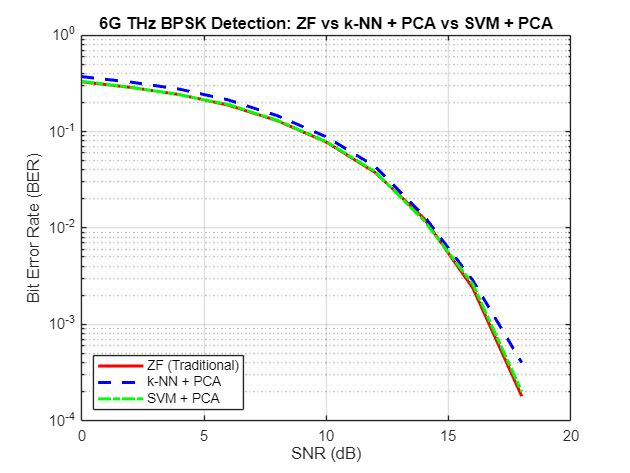


%% --- Plot Comparison
figure;
semilogy(SNR_dB_range, ber_zf, 'r-', 'LineWidth', 2); hold on;
semilogy(SNR_dB_range, ber_knn_pca, 'b--', 'LineWidth', 2);
semilogy(SNR_dB_range, ber_svm_pca, 'g-.', 'LineWidth', 2);
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('6G THz BPSK Detection: ZF vs k-NN + PCA vs SVM + PCA');
legend('ZF (Traditional)', 'k-NN + PCA', 'SVM + PCA', 'Location', 'southwest');
grid on;
ylim([1e-4 1]);
saveas(gcf, 'svm.eps', 'epsc');  % 'epsc' for color EPS